Computes the trajectory of an electon entering a hemholtz

coil with radius a and current I, at initial position (r0,0) and with initial velocity (v0r,v0z) Detailed explanation goes here

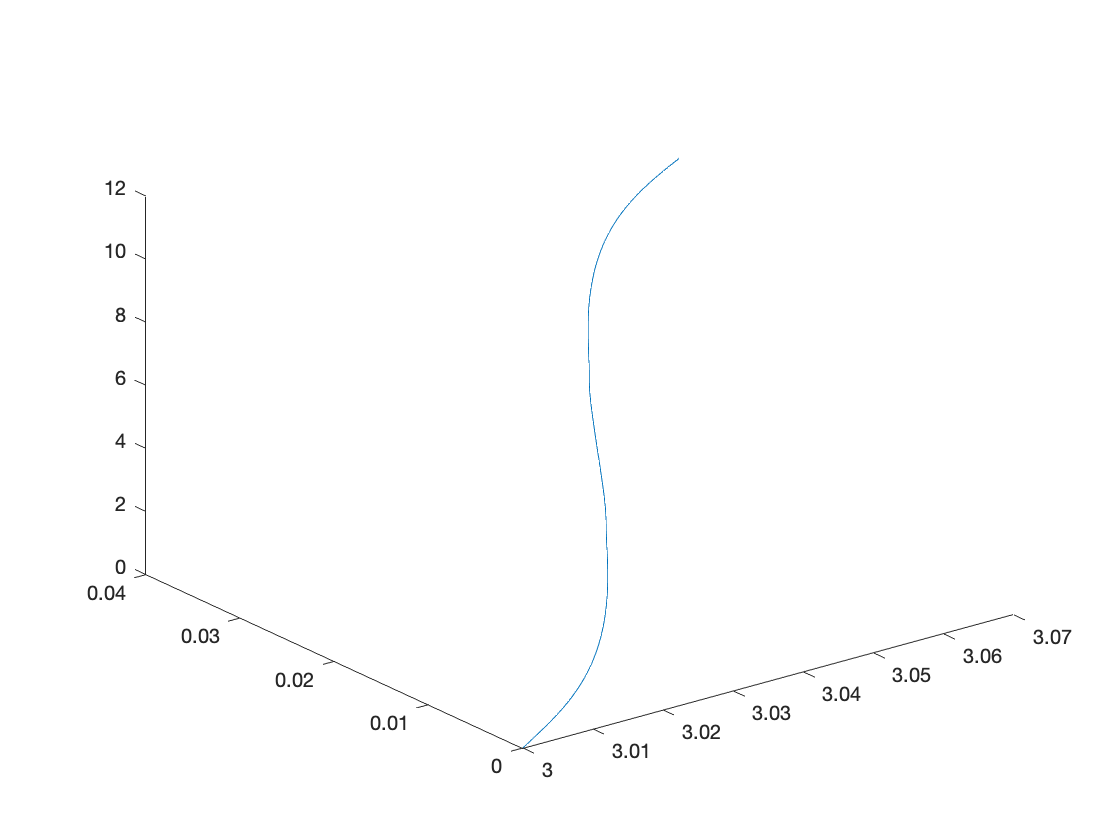

I=1;
a=5;
r0=3;
v0r=0.1;
v0z=15;

z=0:a/100:2*a;
phi=zeros(size(z));
r=zeros(size(z));
r(1)=r0;
vr=zeros(size(z));
vz=zeros(size(z));
vphi=zeros(size(z));
vr(1)=v0r;
vz(1)=v0z;


for i=1:1:size(z,2)-1
    % new position
    z(i+1)=z(i)+a/100;
    r(i+1)=r(i)+vr(i)*a/100/vz(i);
    phi(i+1)=phi(i)+vphi(i)*a/100/vz(i)/r(i);
    
    % acceleration components caused by Lorentz force
    [Brho,Bz]=Bhemholtz(I,a,r(i),z(i));
    az=-vphi(i)*Brho;
    ar=vphi(i)*Bz;
    aphi=-vr(i)*Bz+vz(i)*Brho;
    
    % new velocity (Pay special attention to centripetal and "Coriolis" accelerations)
    vz(i+1)=vz(i)+az*a/100/vz(i);
    vr(i+1)=vr(i)+(ar+(vphi(i))^2/r(i))*a/100/vz(i);
    vphi(i+1)=vphi(i)+(aphi-vr(i)*vphi(i)/r(i))*a/100/vz(i);
end

X=r.*cos(phi);
Y=r.*sin(phi);

plot3(X,Y,z);